# Final Project : Car Detection in a video

Let's start by exploring some properties of the RoadTraffic.mp4 video : 

vTraffic = VideoReader("RoadTraffic.mp4")

vTraffic =   VideoReader with properties:

   General Properties:
            Name: 'RoadTraffic.mp4'
            Path: 'C:\Users\21692\Desktop\coursera\MATLAB\Image Processing for Engineering and Science\Data\MathWorks Images'
        Duration: 24
     CurrentTime: 0.1000
       NumFrames: <Calculating...> learn more

   Video Properties:
           Width: 1158
          Height: 518
       FrameRate: 10
    BitsPerPixel: 24
     VideoFormat: 'RGB24'



## Preprocessing the video

The main goal here is to preprocess the video by removing the noise from the frames. 

We'll work with frames 96, 113 and 227 in order to test our function.

We'll produce a function a removes the noise from the frames and converts them to grayscale. The final output will be stored in a new video.

Let's get started.

frame_96 = read(vTraffic,96);
frame_113 = read(vTraffic,113);
frame_227 = read(vTraffic,227);

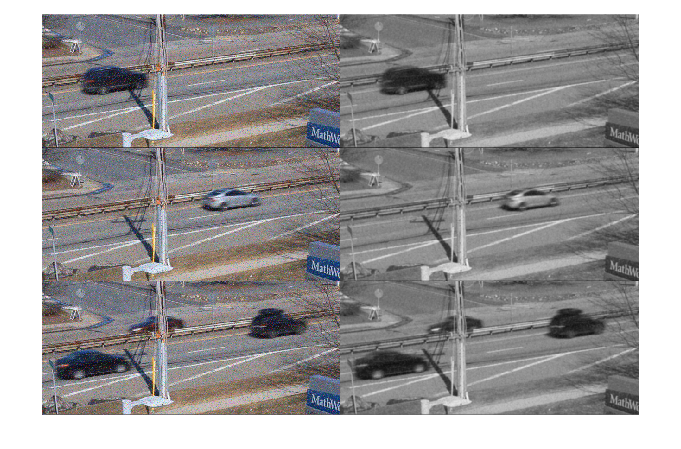

filtered_96 = enhanceImage(frame_96);
filtered_113 = enhanceImage(frame_113);
filtered_227 = enhanceImage(frame_227);

montage({frame_96,filtered_96,frame_113,filtered_113,frame_227,filtered_227})

## Isolating cars

Now that the video is filtered and converted it to grayscale, the next step is to use image segmentation to isolate the cars driving on the road. The end result of this section is to have a process for taking frames from the video and generates segmented masks.

#### Challenge 1: The telephone pole

A significant issue encountered in a few frames is how to account for the telephone pole in front of the road like the 10th frame of the video.

#### Challenge 2: Light vs dark cars

In your grayscale video, cars can be light, dark, or in-between suc as in frame 153.

#### Challenge 3: Overlapping cars

Another challenge is when cars in the two lanes overlap, such as found in frame 225.

Let's move ahead and give it a try.

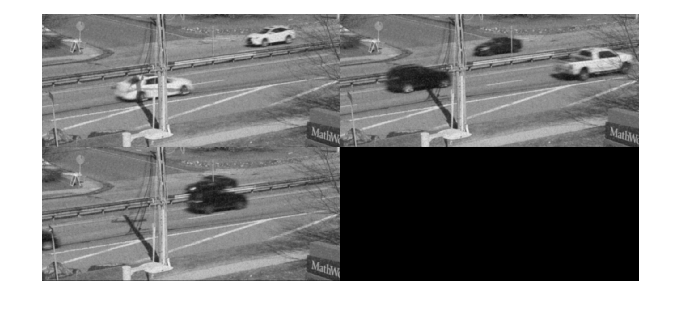

frame_153 = enhanceImage(read(vTraffic,153));
frame_10 = enhanceImage(read(vTraffic,10));
frame_225 = enhanceImage(read(vTraffic,225));
montage({frame_10,frame_153,frame_225})

As we can see, we cannot directly segment cars from these frames as the colors overlap with some other components in the image. 

But let's have a look at the first frame in the video

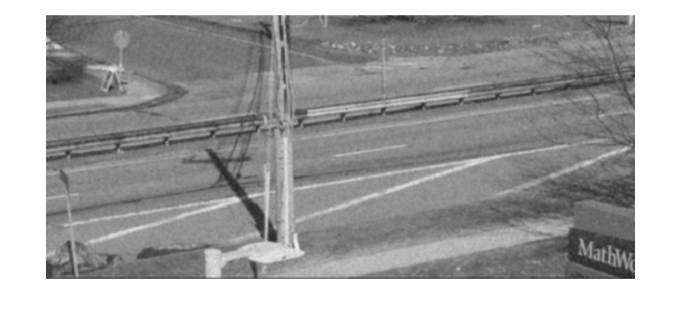

imshow(enhanceImage(read(vTraffic,1)))

So the main scheme of our approach would be to segment the image that results from the substraction of the original frame and the background. Let's dive in !

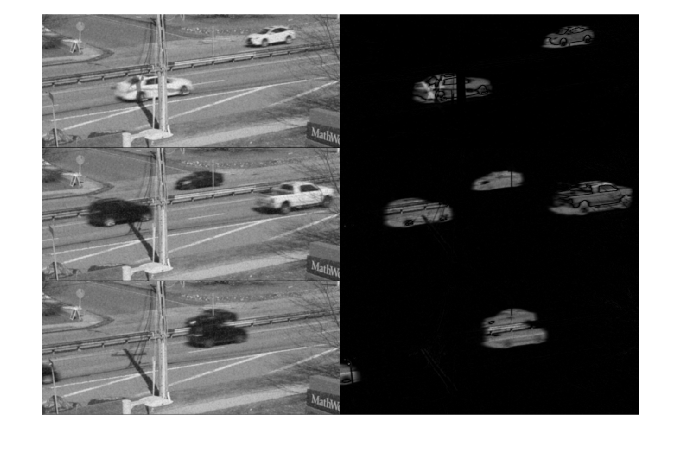

bg = enhanceImage(read(vTraffic,1));
frame_cars_10 = im2double(frame_10);
frame_cars_153 = im2double(frame_153);
frame_cars_225 = im2double(frame_225);

bg_road = im2double(bg);
substracted_10 = abs(frame_cars_10 - bg_road);
substracted_153 = abs(frame_cars_153- bg_road);
substracted_225 = abs(frame_cars_225 - bg_road);
montage({frame_cars_10,substracted_10,frame_cars_153,substracted_153,frame_cars_225,substracted_225})

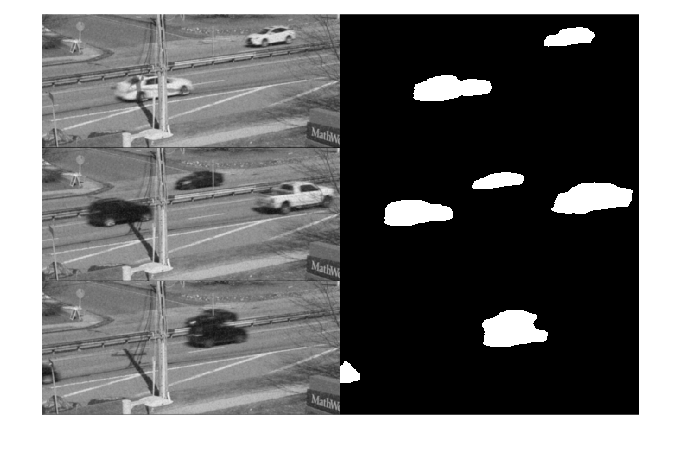

[BW_10,MaskedCars_10] = segmentCarTraffic(substracted_10);
[BW_153,MaskedCars_153] = segmentCarTraffic(substracted_153);
[BW_225,MaskedCars_225] = segmentCarTraffic(substracted_225);
montage({frame_cars_10,BW_10,frame_cars_153,BW_153,frame_cars_225,BW_225})

frame_cars_109 = im2double(enhanceImage(read(vTraffic,201)));
bg_road = im2double(bg);
substracted_109 = abs(frame_cars_109 - bg_road);


## Calculating region properties

Now we need to apply the segmentation process to the whole video so that we can statistically analyze the regions found in each frame.

In this section, the goal is to summarize the region information for each frame. Specifically, we will create a table that contains a row for each frame of the video and a column for these three properties:

- number of regions

- mean region size

- total region size

numFrames_vTraffic = vTraffic.NumFrames;
v_seg= VideoWriter("BinaryVideo","MPEG-4");
v_seg_comb= VideoWriter("BinaryVideoCombined","MPEG-4");

v_seg.FrameRate = vTraffic.FrameRate;
v_seg_comb.FrameRate = vTraffic.FrameRate;
open(v_seg);
NumberRegions =[];
MeanRegionSize = [];
TotalRegionSize = [];
for i = 1 : numFrames_vTraffic
    frame = read(vTraffic,i);
    frame_cars = enhanceImage(frame);
    frame_bg = abs(im2double(frame_cars) - bg_road);
    [BW,maskedImage] = segmentCarTraffic(frame_bg);
    writeVideo(v_seg, im2uint8(BW));
    
    [BW_out,properties] = GetAreas(BW);
    Areas = properties.Area;
    NumberRegions = [NumberRegions ; length(Areas)];
    MeanRegionSize = [MeanRegionSize ; mean(Areas)];
    TotalRegionSize = [TotalRegionSize ; sum(Areas)];

end
close(v_seg);

CarData = table(NumberRegions,MeanRegionSize,TotalRegionSize);

open(v_seg_comb);
for i = 1 : numFrames_vTraffic
    frame = read(vTraffic,i);
    frame_cars = enhanceImage(frame);
    frame_bg = abs(im2double(frame_cars) - bg_road);
    [BW,maskedImage] = segmentCarTraffic(frame_bg);
    props = regionprops("table",BW,"BoundingBox");
    BoxedCars =insertShape(frame,"Rectangle",props.BoundingBox,"LineWidth",3,"Color","green");
    img = imfuse(BoxedCars,BW,"montage");
    writeVideo(v_seg_comb, img);
end
close(v_seg_comb);